# Análisis rieles

A1Central=readtable("MatLab cinetica\Reacciones actuador central\A1.txt","Delimiter"," ");

A1Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

A2Central=readtable("MatLab cinetica\Reacciones actuador central\A2.txt","Delimiter"," ");

A2Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

A3Central=readtable("MatLab cinetica\Reacciones actuador central\A3.txt","Delimiter"," ");

A3Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B1Central=readtable("MatLab cinetica\Reacciones actuador central\B1.txt","Delimiter"," ");

B1Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B2Central=readtable("MatLab cinetica\Reacciones actuador central\B2.txt","Delimiter"," ");

B2Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

B3Central=readtable("MatLab cinetica\Reacciones actuador central\B3.txt","Delimiter"," ");

B3Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C1Central=readtable("MatLab cinetica\Reacciones actuador central\C1.txt","Delimiter"," ");

C1Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C2Central=readtable("MatLab cinetica\Reacciones actuador central\C2.txt","Delimiter"," ");

C2Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

C3Central=readtable("MatLab cinetica\Reacciones actuador central\C3.txt","Delimiter"," ");

C3Central.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

CargaAxialCentralA1=-A1Central.Fz;
CargaAxialCentralA2=-A2Central.Fz;
CargaAxialCentralA3=-A3Central.Fz;

CargaAxialCentralB1=-B1Central.Fz;
CargaAxialCentralB2=-B2Central.Fz;
CargaAxialCentralB3=-B3Central.Fz;

CargaAxialCentralC1=-C1Central.Fz;
CargaAxialCentralC2=-C2Central.Fz;
CargaAxialCentralC3=-C3Central.Fz;

CargaAvanceCentralA1=A1Central.Fx;
CargaAvanceCentralA2=A2Central.Fx;
CargaAvanceCentralA3=A3Central.Fx;

CargaAvanceCentralB1=B1Central.Fx;
CargaAvanceCentralB2=B2Central.Fx;
CargaAvanceCentralB3=B3Central.Fx;

CargaAvanceCentralC1=C1Central.Fx;
CargaAvanceCentralC2=C2Central.Fx;
CargaAvanceCentralC3=C3Central.Fx;



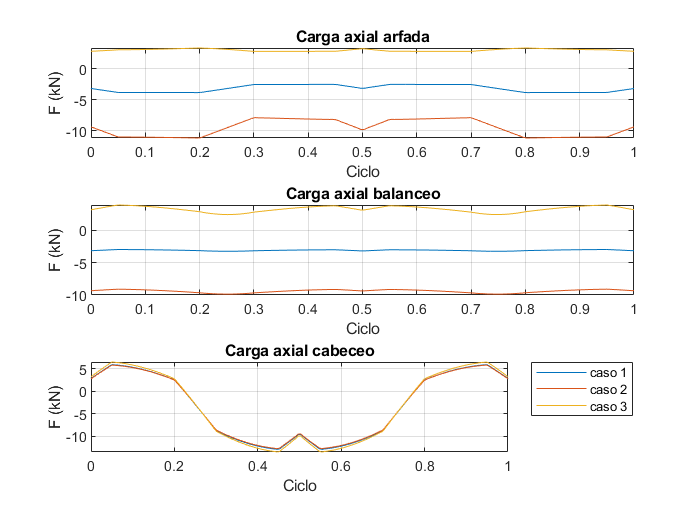

figure()
subplot(3,1,1)
plot(linspace(0,1,160),CargaAxialCentralA1/1000)
hold on
plot(linspace(0,1,160),CargaAxialCentralA2/1000)
plot(linspace(0,1,160),CargaAxialCentralA3/1000)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga axial arfada")
xlabel('Ciclo')
ylabel('F (kN)')
grid on

subplot(3,1,2)
plot(linspace(0,1,160),CargaAxialCentralB1/1000)
hold on
plot(linspace(0,1,160),CargaAxialCentralB2/1000)
plot(linspace(0,1,160),CargaAxialCentralB3/1000)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga axial balanceo")
xlabel('Ciclo')
ylabel('F (kN)')
grid on


subplot(3,1,3)
plot(linspace(0,1,160),CargaAxialCentralC1/1000)
hold on
plot(linspace(0,1,160),CargaAxialCentralC2/1000)
plot(linspace(0,1,160),CargaAxialCentralC3/1000)
hold off
legend("caso 1","caso 2","caso 3","Location","bestoutside")
title("Carga axial cabeceo")
xlabel('Ciclo')
ylabel('F (kN)')
grid on

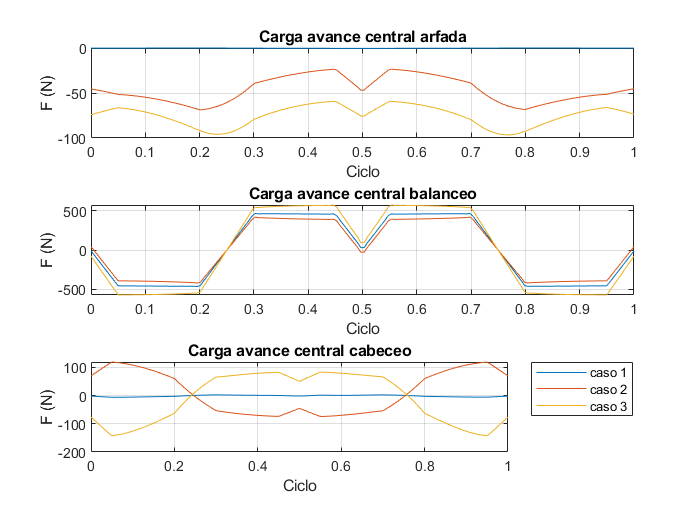



figure()
subplot(3,1,1)
plot(linspace(0,1,160),CargaAvanceCentralA1)
hold on
plot(linspace(0,1,160),CargaAvanceCentralA2)
plot(linspace(0,1,160),CargaAvanceCentralA3)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga avance central arfada")
xlabel('Ciclo')
ylabel('F (N)')
grid on

subplot(3,1,2)
plot(linspace(0,1,160),CargaAvanceCentralB1)
hold on
plot(linspace(0,1,160),CargaAvanceCentralB2)
plot(linspace(0,1,160),CargaAvanceCentralB3)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga avance central balanceo")
xlabel('Ciclo')
ylabel('F (N)')
grid on


subplot(3,1,3)
plot(linspace(0,1,160),CargaAvanceCentralC1)
hold on
plot(linspace(0,1,160),CargaAvanceCentralC2)
plot(linspace(0,1,160),CargaAvanceCentralC3)
hold off
legend("caso 1","caso 2","caso 3","Location","bestoutside")
title("Carga avance central cabeceo")
xlabel('Ciclo')
ylabel('F (N)')
grid on




maxVCCargaAvanceCentral=max([CargaAvanceCentralA1;CargaAvanceCentralA2;CargaAvanceCentralA3;CargaAvanceCentralB1;CargaAvanceCentralB2;CargaAvanceCentralB3;CargaAvanceCentralC1;CargaAvanceCentralC2;CargaAvanceCentralC3]);
disp("Carga avance central máxima: "+maxVCCargaAvanceCentral+" N")

Carga avance central máxima: 572.804 N


maxVCCargaAxialCentral=max([CargaAxialCentralA1;CargaAxialCentralA2;CargaAxialCentralA3;CargaAxialCentralB1;CargaAxialCentralB2;CargaAxialCentralB3;CargaAxialCentralC1;CargaAxialCentralC2;CargaAxialCentralC3]);
disp("Carga axial máxima: "+maxVCCargaAxialCentral+" N")

Carga axial máxima: 6462.79 N


A3Ejes=readtable("MatLab cinetica\Reacciones para rieles\A3.txt","Delimiter"," ");

A3Ejes.Properties.VariableNames=["T","Fxd","Fyd","Fxi","Fyi"];


B3Ejes=readtable("MatLab cinetica\Reacciones para rieles\B3.txt","Delimiter"," ");

B3Ejes.Properties.VariableNames=["T","Fxd","Fyd","Fxi","Fyi"];

C3Ejes=readtable("MatLab cinetica\Reacciones para rieles\C3.txt","Delimiter"," ");

C3Ejes.Properties.VariableNames=["T","Fxd","Fyd","Fxi","Fyi"];

CargaEjesAvanceA3d=-A3Ejes.Fxd;

CargaEjesAvanceB3d=-B3Ejes.Fxd;

CargaEjesAvanceC3d=-C3Ejes.Fxd;

CargaEjesAxialA3d=A3Ejes.Fyd;

CargaEjesAxialB3d=B3Ejes.Fyd;

CargaEjesAxialC3d=C3Ejes.Fyd;

CargaEjesAvanceA3i=-A3Ejes.Fxi;

CargaEjesAvanceB3i=-B3Ejes.Fxi;

CargaEjesAvanceC3i=-C3Ejes.Fxi;

CargaEjesAxialA3i=A3Ejes.Fyi;

CargaEjesAxialB3i=B3Ejes.Fyi;

CargaEjesAxialC3i=C3Ejes.Fyi;


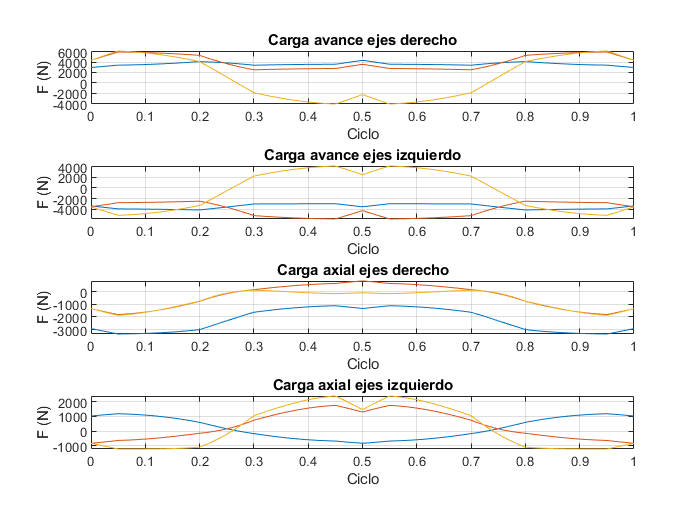

figure()
subplot(4,1,1)
plot(linspace(0,1,160),CargaEjesAvanceA3d)
hold on
plot(linspace(0,1,160),CargaEjesAvanceB3d)
plot(linspace(0,1,160),CargaEjesAvanceC3d)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga avance ejes derecho")
xlabel('Ciclo')
ylabel('F (N)')
grid on

subplot(4,1,2)
plot(linspace(0,1,160),CargaEjesAvanceA3i)
hold on
plot(linspace(0,1,160),CargaEjesAvanceB3i)
plot(linspace(0,1,160),CargaEjesAvanceC3i)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga avance ejes izquierdo")
xlabel('Ciclo')
ylabel('F (N)')
grid on


subplot(4,1,3)
plot(linspace(0,1,160),CargaEjesAxialA3d)
hold on
plot(linspace(0,1,160),CargaEjesAxialB3d)
plot(linspace(0,1,160),CargaEjesAxialC3d)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga axial ejes derecho")
xlabel('Ciclo')
ylabel('F (N)')
grid on

subplot(4,1,4)
plot(linspace(0,1,160),CargaEjesAxialA3i)
hold on
plot(linspace(0,1,160),CargaEjesAxialB3i)
plot(linspace(0,1,160),CargaEjesAxialC3i)
hold off
%legend("caso 1","caso 2","caso 3","Location","best")
title("Carga axial ejes izquierdo")
xlabel('Ciclo')
ylabel('F (N)')
grid on


maxVCCargaAvanceEjesD=max([CargaEjesAvanceA3d;CargaEjesAvanceB3d;CargaEjesAvanceC3d]);
disp("Carga avance ejes derecho máxima: "+maxVCCargaAvanceEjesD+" N")

Carga avance ejes derecho máxima: 6135.5352 N


maxVCCargaAvanceEjesI=max([CargaEjesAvanceA3i;CargaEjesAvanceB3i;CargaEjesAvanceC3i]);
disp("Carga avance ejes izquierdo máxima: "+maxVCCargaAvanceEjesI+" N")

Carga avance ejes izquierdo máxima: 4116.7617 N


maxVCCargaAxialEjesD=max([CargaEjesAxialA3d;CargaEjesAxialB3d;CargaEjesAxialC3d]);
disp("Carga axial ejes derecho máxima: "+maxVCCargaAxialEjesD+" N")

Carga axial ejes derecho máxima: 830.9131 N


maxVCCargaAxialEjesI=max([CargaEjesAxialA3i;CargaEjesAxialB3i;CargaEjesAxialC3i]);
disp("Carga axial ejes izquierdo máxima: "+maxVCCargaAxialEjesI+" N")

Carga axial ejes izquierdo máxima: 2392.6314 N


CargaAvanceA3=CargaEjesAvanceA3d+CargaEjesAvanceA3i+CargaAvanceCentralA3;
CargaAvanceB3=CargaEjesAvanceB3d+CargaEjesAvanceB3i+CargaAvanceCentralB3;
CargaAvanceC3=CargaEjesAvanceC3d+CargaEjesAvanceC3i+CargaAvanceCentralC3;
maxVCCargaAvance=max([CargaAvanceA3;CargaAvanceB3;CargaAvanceC3]);
disp("Carga avance máxima: "+maxVCCargaAvance+" N")

Carga avance máxima: 2628.812 N



CargaAxialA3=CargaEjesAxialA3d+CargaEjesAxialA3i+CargaAxialCentralA3;
CargaAxialB3=CargaEjesAxialB3d+CargaEjesAxialB3i+CargaAxialCentralB3;
CargaAxialC3=CargaEjesAxialC3d+CargaEjesAxialC3i+CargaAxialCentralC3;
maxVCCargaAxial=max([CargaAxialA3;CargaAxialB3;CargaAxialC3]);
disp("Carga axial máxima: "+maxVCCargaAxial+" N")

Carga axial máxima: 6208.3272 N


Los momentos se anulan por las reacciones de los carritos. 

Se necesitan 2 guías lineares y un robot.

PesoMotores=40.5;
PesoReductores=97+22;
PesoCilindro=11.1;
PesoGuia=14;
PesoReductorClindro=6;
PesoKit=12.1;
PesoMotorCilindro=9.6;
PesoCilindroCompleto=PesoCilindro+PesoGuia+PesoReductorClindro+PesoKit+PesoMotorCilindro;
PesoMarcoInferior=46.871;
PesoPlacas=0;

PesoSistemaNotable=(PesoMarcoInferior+PesoMotores+PesoReductores+PesoCilindroCompleto+PesoPlacas)*g

PesoSistemaNotable = 2.5425e+03

Velocidad_Linear_Max

Velocidad_Linear_Max = 0.7500

aMax

aMax = 1.6350

factor_mm_min=1000/0.1666

factor_mm_min = 6.0024e+03

tMax=20*sqrt(327)/327

tMax = 1.1060

Tiempo=tMax-0.65582

Tiempo = 0.4502

Velocidad_Radial_Max_RPM

Velocidad_Radial_Max_RPM = 1800

coeficiente_roz=0.004

coeficiente_roz = 0.0040

eta=0.8

eta = 0.8000

Longitud=550

Longitud = 550



FuerzaAxialSinPeso=maxVCCargaAxial

FuerzaAxialSinPeso = 6.2083e+03

FuerzaAxialCompleta=PesoSistemaNotable+maxVCCargaAxial

FuerzaAxialCompleta = 8.7508e+03

FuerzaAvanceCompleta=maxVCCargaAvance

FuerzaAvanceCompleta = 2.6288e+03


J_carga=(PesoSistemaNotable/g+FuerzaAxialSinPeso)*((Velocidad_Linear_Max*factor_mm_min)/(2*pi*Velocidad_Radial_Max_RPM*10))^2

J_carga = 10.2472

J_base_motor=J_carga/10

J_base_motor = 1.0247

J_motor=13

J_motor = 13

%https://motioncontrolsystems.hiwin.com/item/ac-servo-motors/servo-motor-400w-middle-inertia-small-capacity/frms4b20606a
%https://motioncontrolsystems.hiwin.com/item/ac-servo-motors/servo-motor-2000w-middle-inertia-middle-capacity/frmm2k2b613a

TorqueA=((J_motor+J_carga)*0.0001*0.0001*Velocidad_Radial_Max_RPM)/(9.55*0.0001*Tiempo*0.5)

TorqueA = 1.9466

TorqueL=((FuerzaAxialSinPeso+coeficiente_roz*PesoSistemaNotable/g)*Velocidad_Linear_Max*factor_mm_min)/(2*1000*pi*eta*Velocidad_Radial_Max_RPM)

TorqueL = 3.0895

TorqueTotal=TorqueA+TorqueL

TorqueTotal = 5.0361

Torque_motor=9.55

Torque_motor = 9.5500

Desplazamiento_ciclo=0.2*0.001

Desplazamiento_ciclo = 2.0000e-04

Ciclos_hora=3600/tMax

Ciclos_hora = 3.2550e+03

Lmedia=Desplazamiento_ciclo*Ciclos_hora*10*54*7*24

Lmedia = 5.9058e+04

CargaDinamica=((Lmedia/50)^(1/3))*FuerzaAxialCompleta

CargaDinamica = 9.2502e+04

CargaCarritoAxial=CargaDinamica/5

CargaCarritoAxial = 1.8500e+04